carrier = nrCarrierConfig;
carrier.NSizeGrid = 52;
carrier.SubcarrierSpacing = 15;
rng("default") % Enable reproducible simulation results
channel = nrCDLChannel;
channel.DelayProfile = 'CDL-C';
channel.DelaySpread = 300e-9;
channel.MaximumDopplerShift = 5;
channel.TransmitAntennaArray.Size = [1 2 2 1 1];
channel.ReceiveAntennaArray.Size = [1 1 2 1 1];
nTxAnts = prod(channel.TransmitAntennaArray.Size);
nRxAnts = prod(channel.ReceiveAntennaArray.Size);
ofdmInfo = nrOFDMInfo(carrier);
channel.SampleRate = ofdmInfo.SampleRate;
SNRdB = 10;
SNR = 10^(SNRdB/10);
[pdsch,pdschSymbols,pdschIndices,w,resourceGrid] = pdschConfigurationAndMapping(carrier,nTxAnts);
channel.ChannelFiltering = false;
nSlotSamples = sum(ofdmInfo.SymbolLengths(1:ofdmInfo.SymbolsPerSlot));
channel.NumTimeSamples = nSlotSamples;
slotLength = 0.01 / carrier.SlotsPerFrame;
symbolLength = slotLength / carrier.SymbolsPerSlot

symbolLength = 7.1429e-05

channelCoherenceTime = 1/channel.MaximumDopplerShift

channelCoherenceTime = 0.2000

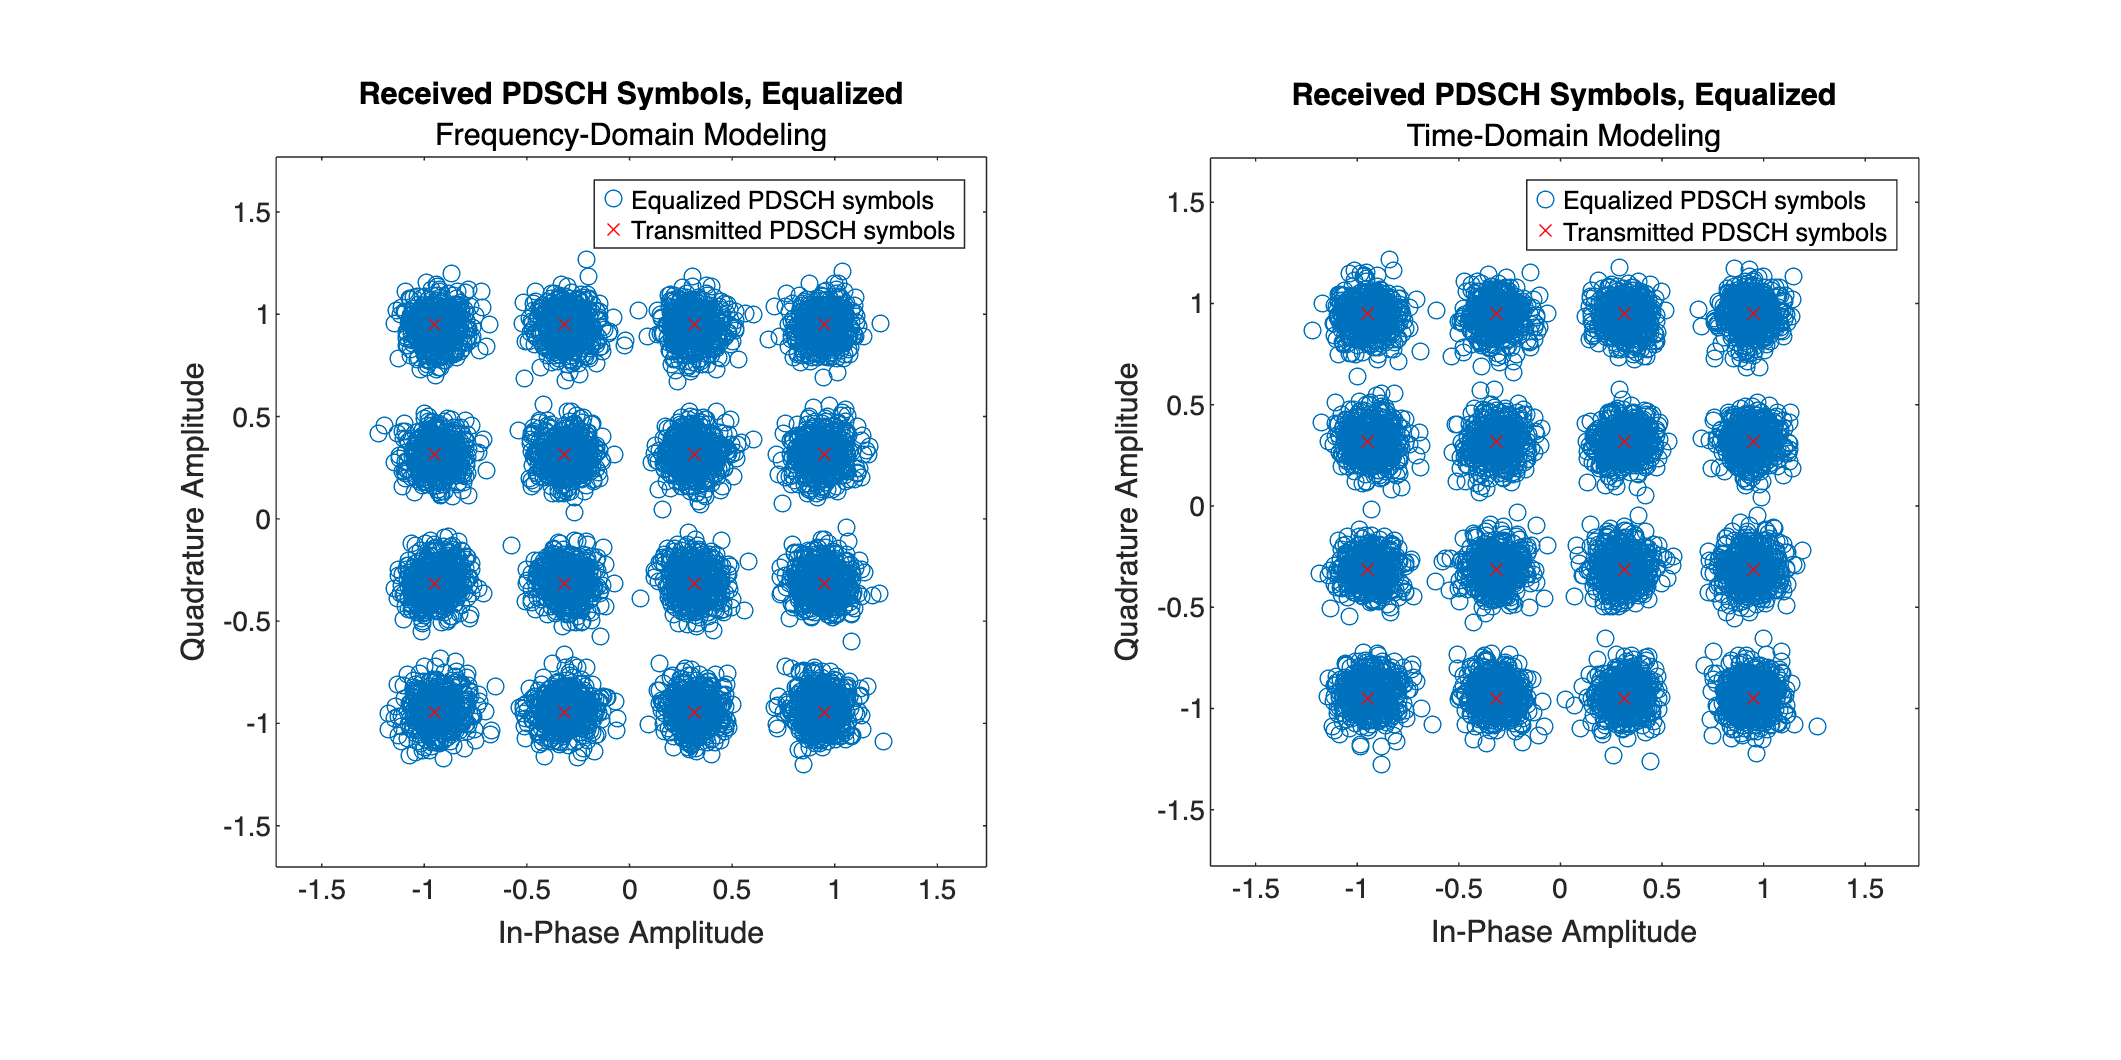

[pathGains,sampleTimes] = channel();
pathFilters = getPathFilters(channel);
[rxGrid,ofdmChannelResponse] = hApplyFrequencyDomainChannel(carrier,pathGains,pathFilters,sampleTimes,resourceGrid);
N0 = 1 / sqrt(nRxAnts*SNR);
noiseGrid = N0*randn(size(rxGrid),'like',rxGrid);
rxGrid = rxGrid + noiseGrid;
noiseEst = N0^2;
pdschEq = equalizePDSCH(carrier,pdsch,rxGrid,w,ofdmChannelResponse,noiseEst);
reset(channel)
release(channel)
channel.ChannelFiltering = true;
txWaveform = nrOFDMModulate(carrier,resourceGrid);
[rxWaveform,timePathGains,timeSampleTimes,timeNoise] = timeDomainChannelFiltering(txWaveform,ofdmInfo,channel,nRxAnts,SNR);
timePathFilters = getPathFilters(channel);
timePDSCHEq = timeDomainReceiver(carrier,pdsch,rxWaveform,w,timePathFilters,timePathGains,timeSampleTimes,timeNoise);
plotSymbols(pdschEq,timePDSCHEq,pdschSymbols)

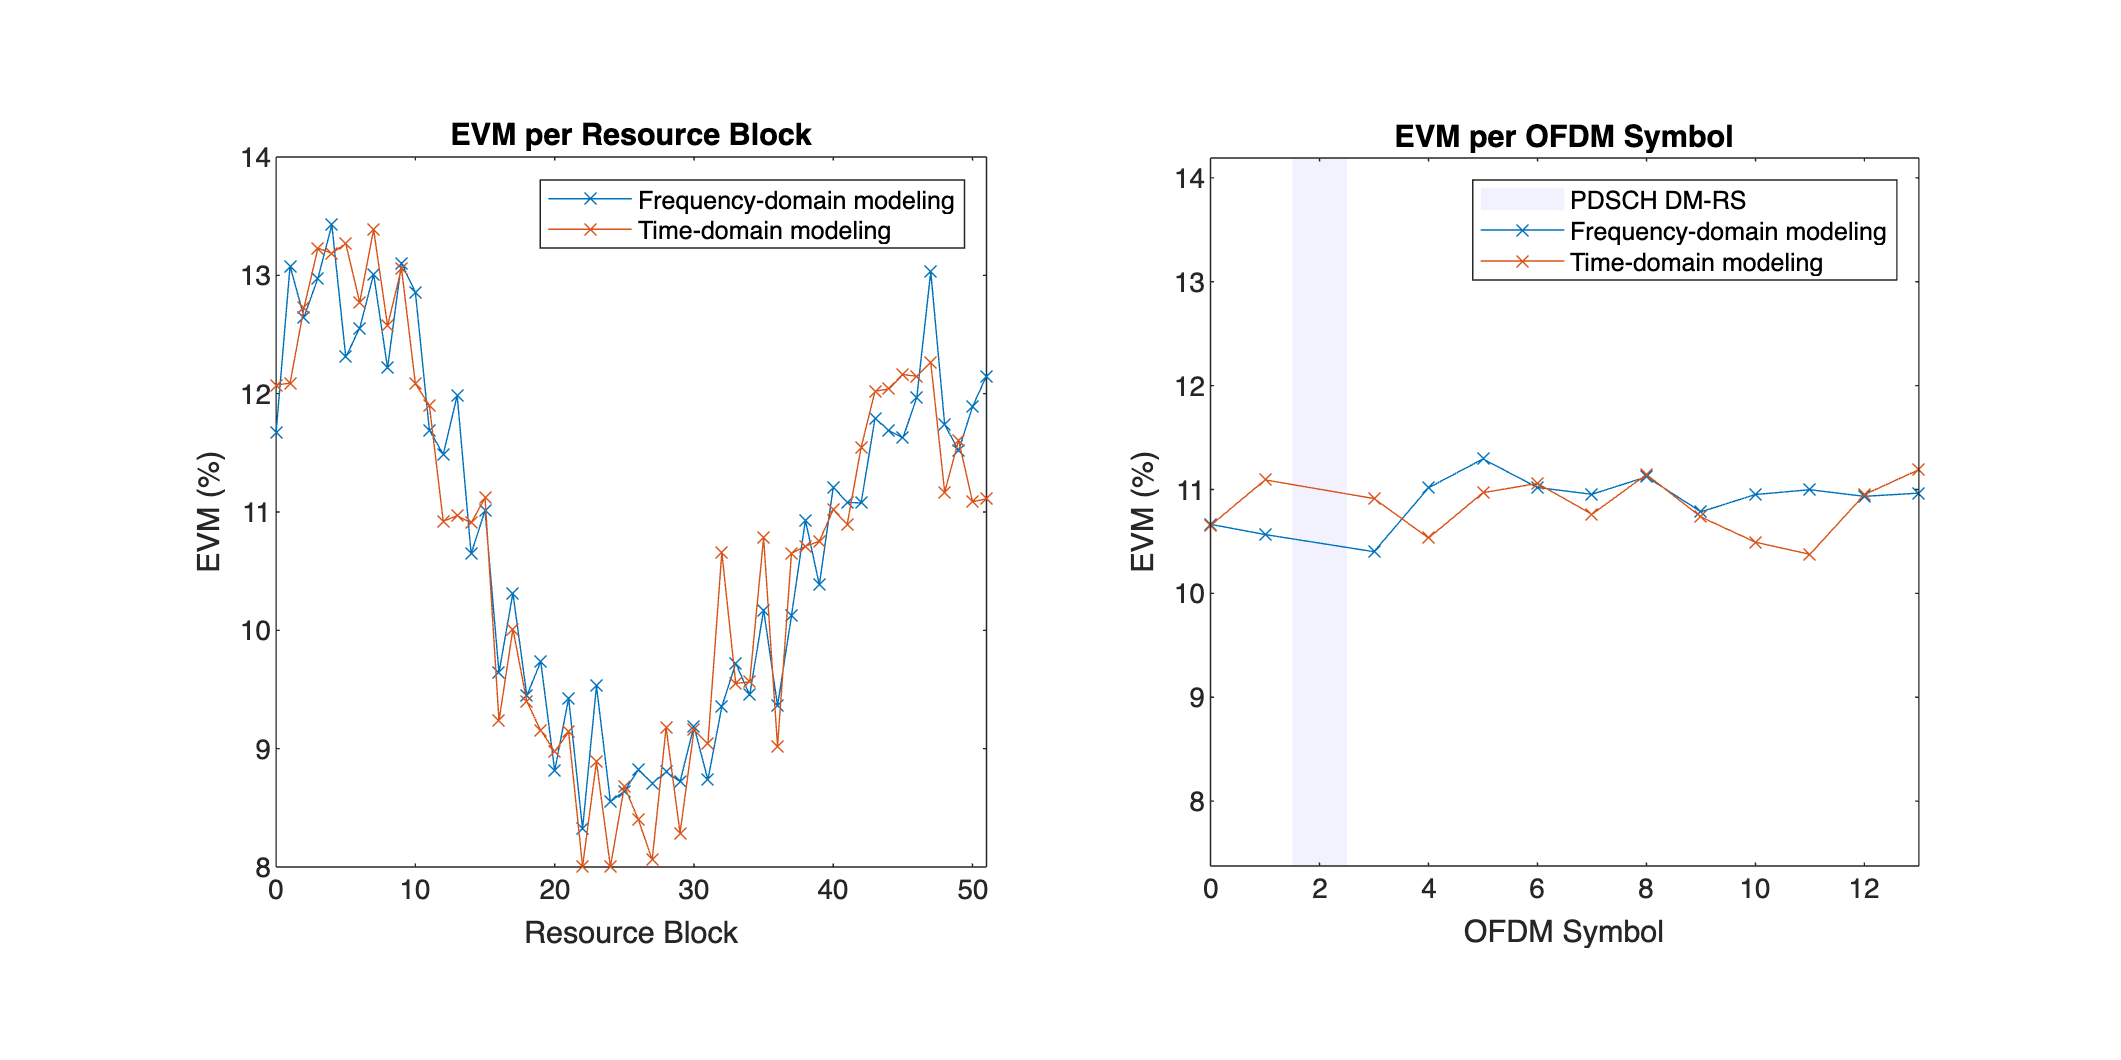

fig2 = figure();
subplot(1,2,1)
evmPerRB_freq = plotEVM(pdsch,pdschIndices,size(resourceGrid),pdschSymbols,pdschEq,'perRB');
hold on
evmPerRB_time = plotEVM(pdsch,pdschIndices,size(resourceGrid),pdschSymbols,timePDSCHEq,'perRB');
legend(["Frequency-domain modeling","Time-domain modeling"])
axis square
hold off
subplot(1,2,2)
axis manual
fill([1.5 1.5 2.5 2.5], [0 100 100 0], 'b','FaceAlpha',0.05,'EdgeColor','none');
hold on
evmPerSym_freq = plotEVM(pdsch,pdschIndices,size(resourceGrid),pdschSymbols,pdschEq,'perSym');
evmPerSym_time = plotEVM(pdsch,pdschIndices,size(resourceGrid),pdschSymbols,timePDSCHEq,'perSym');
legend(["PDSCH DM-RS","Frequency-domain modeling","Time-domain modeling"])
axis square
hold off
set(fig2, 'Position', [0 0 1000 500])

nFrames = 10;
[freqExecutionTime,timeExecutionTime] = compareExecutionTime(carrier,ofdmInfo,channel,nFrames,nTxAnts,nRxAnts,SNR);

for x = 1
    fprintf("Frequency-domain execution time: %f seconds\n",freqExecutionTime)
    fprintf("Time-domain execution time:      %f seconds\n",timeExecutionTime)
end

Frequency-domain execution time: 1.084252 seconds


Time-domain execution time:      4.862128 seconds


function [pdsch,pdschSymbols,pdschIndices,w,resourceGrid] = pdschConfigurationAndMapping(carrier,nTxAnts)
    pdsch = nrPDSCHConfig;
    pdsch.Modulation = "16QAM";
    pdsch.NumLayers = 1;
    pdsch.PRBSet = 0:carrier.NSizeGrid-1; % Full band allocation
    
    [pdschIndices,pdschInfo] = nrPDSCHIndices(carrier,pdsch);
    pdschBits = randi([0 1],pdschInfo.G,1);
    pdschSymbols = nrPDSCH(carrier,pdsch,pdschBits);
    
    dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
    dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);
    
    % Precoding weights
    W = fft(eye(nTxAnts))/sqrt(nTxAnts);              % Unitary precoding matrix
    w = W(1:pdsch.NumLayers,:)/sqrt(pdsch.NumLayers); % Normalize by number of layers
    
    pdschSymbolsPrecoded = pdschSymbols*w;
    resourceGrid = nrResourceGrid(carrier,nTxAnts);
    
    [~,pdschAntIndices] = nrExtractResources(pdschIndices,resourceGrid);
    resourceGrid(pdschAntIndices) = pdschSymbolsPrecoded;
    
    % PDSCH DM-RS precoding and mapping
    for p = 1:size(dmrsSymbols,2)
        [~,dmrsAntIndices] = nrExtractResources(dmrsIndices(:,p),resourceGrid);
        resourceGrid(dmrsAntIndices) = resourceGrid(dmrsAntIndices) + dmrsSymbols(:,p)*w(p,:);
    end
end

function pdschEq = equalizePDSCH(carrier,pdsch,rxGrid,w,estChannelGrid,noiseEst)
    [pdschIndices,~] = nrPDSCHIndices(carrier,pdsch);
    [pdschRx,pdschHest,~,pdschHestIndices] = nrExtractResources(pdschIndices,rxGrid,estChannelGrid);
    pdschHest = nrPDSCHPrecode(carrier,pdschHest,pdschHestIndices,permute(w,[2 1 3]));
    [pdschEq,~] = nrEqualizeMMSE(pdschRx,pdschHest,noiseEst);
end

function  [rxWaveform,timePathGains,timeSampleTimes,timeNoise] = timeDomainChannelFiltering(txWaveform,ofdmInfo,channel,nRxAnts,SNR)
    chInfo = info(channel);
    maxChDelay = chInfo.MaximumChannelDelay;
    
    % Pass this waveform through the channel and obtain a received waveform, channel path gains and channel sample times.
    txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))];
    [rxWaveform,timePathGains,timeSampleTimes] = channel(txWaveform);
    
    % Use SNR to generate time domain noise
    timeN0 = 1/sqrt(nRxAnts*double(ofdmInfo.Nfft)*SNR);
    timeNoise = timeN0*randn(size(rxWaveform),'like',rxWaveform);
    
    rxWaveform = rxWaveform + timeNoise;
end
    
function timePDSCHEq = timeDomainReceiver(carrier,pdsch,rxWaveform,w,timePathFilters,timePathGains,timeSampleTimes,timeNoise) 
    % Get the perfect timing offset that should be applied to the received waveform.
    timeOffset = nrPerfectTimingEstimate(timePathGains,timePathFilters);
    estChannelGrid = nrPerfectChannelEstimate(carrier,timePathGains,timePathFilters,timeOffset,timeSampleTimes);

    % Get perfect noise estimate (from the noise realization)
    timeNoiseGrid = nrOFDMDemodulate(carrier,timeNoise(1+timeOffset:end ,:));
    timeNoiseEst = var(timeNoiseGrid(:));
    
    % Offset received waveform
    rxWaveform = rxWaveform(1+timeOffset:end,:);
    
    % Use the function nrOFDMDemodulate to generate the received resource grid.
    timeRxGrid = nrOFDMDemodulate(carrier,rxWaveform);

    timePDSCHEq = equalizePDSCH(carrier,pdsch,timeRxGrid,w,estChannelGrid,timeNoiseEst);
end

function plotSymbols(pdschEq,timePDSCHEq,pdschSymbols)
    fig1 = figure;
    subplot(1,2,1)
    plot(pdschEq(:),"o");
    hold on;
    plot(pdschSymbols(:),"rx");
    xlim([min(real(pdschEq(:)))-0.5 max(real(pdschEq(:)))+0.5])
    ylim([min(imag(pdschEq(:)))-0.5 max(imag(pdschEq(:)))+0.5])
    title("Received PDSCH Symbols, Equalized");
    subtitle("Frequency-Domain Modeling");
    xlabel("In-Phase Amplitude");
    ylabel("Quadrature Amplitude");
    legend(["Equalized PDSCH symbols" "Transmitted PDSCH symbols"]);
    axis square;
    hold off
    subplot(1,2,2)
    plot(timePDSCHEq(:),"o");
    hold on;
    plot(pdschSymbols(:),"rx");
    xlim([min(real(timePDSCHEq(:)))-0.5 max(real(timePDSCHEq(:)))+0.5])
    ylim([min(imag(timePDSCHEq(:)))-0.5 max(imag(timePDSCHEq(:)))+0.5])
    title("Received PDSCH Symbols, Equalized");
    subtitle("Time-Domain Modeling");
    xlabel("In-Phase Amplitude");
    ylabel("Quadrature Amplitude");
    legend(["Equalized PDSCH symbols" "Transmitted PDSCH symbols"]);
    axis square;
    hold off
    set(fig1,'Position',[0 0 1000 500])
end

function evm = plotEVM(pdsch,pdschIndices,siz,pdschSymbols,pdschEq,type)
    rbEVM = comm.EVM;
    symEVM = comm.EVM;
    NRB = siz(1) / 12;
    Nsym = siz(2);
    evmPerRB = NaN(NRB,pdsch.NumLayers);
    evmPerSym = NaN(Nsym,pdsch.NumLayers);
    [k,l,m] = ind2sub(siz,pdschIndices);
    rbsubs = floor((k-1) / 12);
    symsubs = l;
    for nu = 1:pdsch.NumLayers
        if strcmp(type,'perRB')
            for rb = unique(rbsubs).'
                this = (rbsubs==rb & m==nu);
                evmPerRB(rb+1,nu) = rbEVM(pdschSymbols(this),pdschEq(this));
            end
            evm = evmPerRB;
        elseif strcmp(type,'perSym')
            for sym = unique(symsubs).'
                this = (symsubs==sym & m==nu);
                evmPerSym(sym,nu) = symEVM(pdschSymbols(this),pdschEq(this));
            end
            evmPerSym = rmmissing(evmPerSym);
            evm = evmPerSym;
        end
    end
    if strcmp(type,'perRB')
        plot(0:NRB-1,evmPerRB,'x-');
        xlabel('Resource Block');
        ylabel('EVM (%)');
        xlim([0 NRB-1]);
        title('EVM per Resource Block');
    elseif strcmp(type,'perSym')
        plot(unique(symsubs)-1,evmPerSym,'x-');
        xlabel('OFDM Symbol');
        ylabel('EVM (%)');
        xlim([0 Nsym-1]);
        ylim([min(evmPerSym(:))-3 max(evmPerSym(:))+3])
        title('EVM per OFDM Symbol');
    end
end

function [freqTime,timeTime] = compareExecutionTime(carrier,ofdmInfo,channel,nFrames,nTxAnts,nRxAnts,SNR)
    % Reset channel object
    reset(channel)
    % Get path filters from nrCDLChannel object
    pathFilters = getPathFilters(channel);
    
    % Calculate the number of slots from the slots per frame
    nSlots = nFrames * carrier.SlotsPerFrame;

    tic
    for slot = 1:nSlots-1
        carrier.NSlot = slot;
        [pdsch,~,~,w,pdschGrid] = pdschConfigurationAndMapping(carrier,nTxAnts);
        txWaveform = nrOFDMModulate(carrier,pdschGrid);
        [rxWaveform,timePathGains,timeSampleTimes,timeNoise] = timeDomainChannelFiltering(txWaveform,ofdmInfo,channel,nRxAnts,SNR);
        timePDSCHEq = timeDomainReceiver(carrier,pdsch,rxWaveform,w,pathFilters,timePathGains,timeSampleTimes,timeNoise);
    end
    timeTime = toc;

    reset(channel)
    release(channel)
    channel.ChannelFiltering = false;

    tic
    for slot = 1:nSlots-1
        carrier.NSlot = slot;
        [pdsch,~,~,w,pdschGrid] = pdschConfigurationAndMapping(carrier,nTxAnts);
        [pathGains,sampleTimes] = channel();
        [rxGrid,ofdmChannelResponse] = hApplyFrequencyDomainChannel(carrier,pathGains,pathFilters,sampleTimes,pdschGrid);
        N0 = 1 / sqrt(nRxAnts*SNR);
        noiseGrid = N0*randn(size(rxGrid),'like',rxGrid);
        rxGrid = rxGrid + noiseGrid;
        noiseEst = N0^2;
        pdschEq = equalizePDSCH(carrier,pdsch,rxGrid,w,ofdmChannelResponse,noiseEst);
    end
    freqTime = toc;
end